# Revision del dataset banknote paso a paso

Mismo esquema que con Iris, una tabla por paso en el workspace

clear; close all; clc

## Paso 0: dato crudo

datos = load('data_banknote_authentication.txt');
T = array2table(datos(:,1:4), 'VariableNames', {'varianza','asimetria','curtosis','entropia'});
T.clase = categorical(datos(:,5), [0 1], {'autentico','falso'});
vars = T.Properties.VariableNames(1:4);
T0_crudo = T;
summary(T0_crudo)


T0_crudo: 1372×5 table

Variables:

    varianza: double
    asimetria: double
    curtosis: double
    entropia: double
    clase: categorical (2 categories)

Statistics for applicable variables:

                 NumMissing        Min           Median           Max           Mean           Std    

    varianza         0            -7.0421         0.4962         6.8248         0.4337        2.8428  
    asimetria        0           -13.7731         2.3197        12.9516         1.9224        5.8690  
    curtosis         0            -5.2861         0.6166        17.9274         1.3976        4.3100  
    entropia         0            -8.5482        -0.5867         2.4495        -1.1917        2.1010  
    clase            0                                                                                



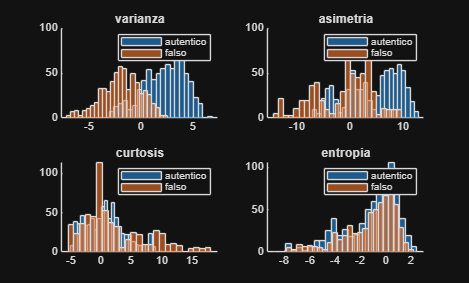


figure
for k = 1:4
    subplot(2,2,k); hold on
    for c = categories(T.clase)'
        histogram(T.(vars{k})(T.clase == c{1}), 25, 'DisplayName', c{1})
    end
    title(vars{k}); legend
end

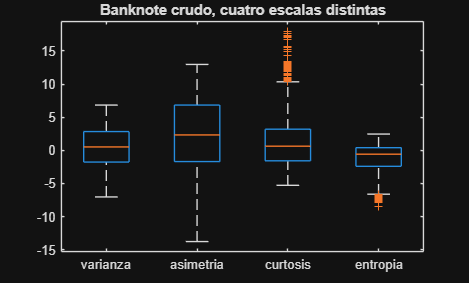


figure
boxplot(T{:,vars}, 'Labels', vars); title('Banknote crudo, cuatro escalas distintas')

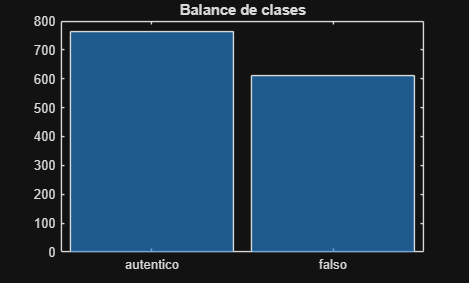


figure
histogram(T.clase); title('Balance de clases')

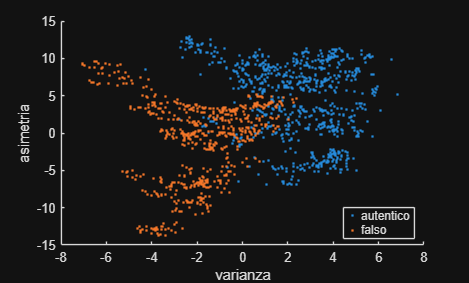


figure
gscatter(T.varianza, T.asimetria, T.clase)
xlabel('varianza'); ylabel('asimetria')

## Paso 1: outliers con la regla 1.5*IQR, recortando al borde

T1_outliers = T0_crudo;
for k = 1:4
    x = T1_outliers.(vars{k});
    q = quantile(x, [0.25 0.75]);
    li = q(1) - 1.5*(q(2)-q(1));  ls = q(2) + 1.5*(q(2)-q(1));
    fuera(k) = sum(x < li | x > ls);
    x(x < li) = li;  x(x > ls) = ls;
    T1_outliers.(vars{k}) = x;
end
fuera

fuera =      0     0    57    33


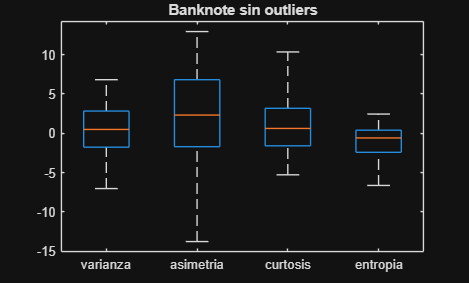

figure
boxplot(T1_outliers{:,vars}, 'Labels', vars); title('Banknote sin outliers')

## Paso 2: balanceo, 610 autenticos al azar para igualar a los 610 falsos

rng(1)
falsos = T1_outliers(T1_outliers.clase == 'falso', :);
autenticos = T1_outliers(T1_outliers.clase == 'autentico', :);
autenticos = autenticos(randperm(height(autenticos), height(falsos)), :);
T2_balanceado = [autenticos; falsos];
countcats(T2_balanceado.clase)'

ans =    610   610


## Paso 3: estandarizar

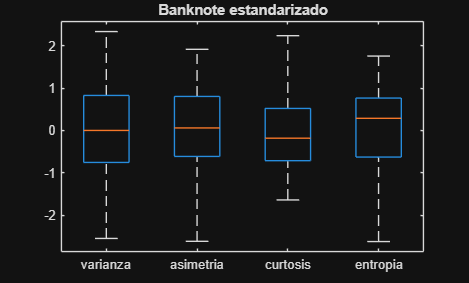

T3_estandarizado = T2_balanceado;
T3_estandarizado{:,vars} = zscore(T2_balanceado{:,vars});
figure
boxplot(T3_estandarizado{:,vars}, 'Labels', vars); title('Banknote estandarizado')

## Paso 4: normalizar entre 0 y 1 (parte del balanceado)

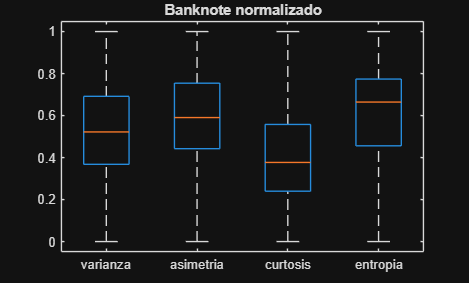

T4_normalizado = T2_balanceado;
T4_normalizado{:,vars} = normalize(T2_balanceado{:,vars}, 'range');
figure
boxplot(T4_normalizado{:,vars}, 'Labels', vars); title('Banknote normalizado')


save('banknote_pasos.mat', 'T0_crudo', 'T1_outliers', 'T2_balanceado', 'T3_estandarizado', 'T4_normalizado')